data = loadCampaign()

data = struct with fields:
     acc: [100000001×2 double]
    ai_d: [103427×2 double]
    ai_u: [103403×2 double]
       T: 0.26
     tau: 1.7e-05


Load `campaign4a.h5`. Note that the lengths of `ai_u` and `ai_d `are different, and timestamps probably aren't related.

Let's look at the distribution of time delays between successive interferometer runs in ai_d

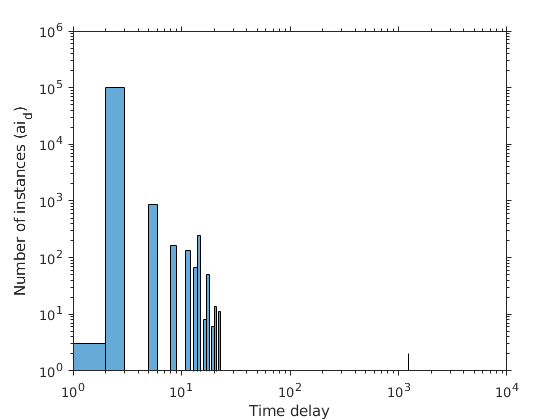

histogram(diff(data.ai_d(:,1)))
set(gca,'yscale','log','xscale','log','TickDir','Out','Color','w')
xlabel('Time delay')
ylabel('Number of instances (ai_d)')

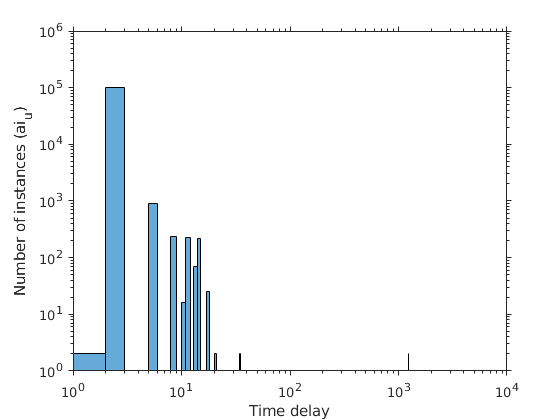


histogram(diff(data.ai_u(:,1)))
set(gca,'yscale','log','xscale','log','TickDir','Out','Color','w')
xlabel('Time delay')
ylabel('Number of instances (ai_u)')

Let's do the same thing for successive interferometer measurements

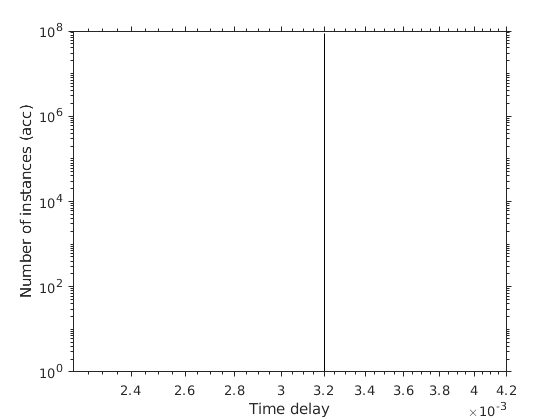

histogram(diff(data.acc(:,1)))
set(gca,'yscale','log','xscale','log','TickDir','Out','Color','w')
xlabel('Time delay')
ylabel('Number of instances (acc)')

However:

diff_acc = diff(data.acc(:,1))

diff_acc =        0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00319957733154297
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00319957733154297
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00319957733154297
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00319957733154297
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005416870117
       0.00320005

[C,ia,ic] = unique(diff_acc);
unique_counts = accumarray(ic,1);
unique_counts = [C,unique_counts]

unique_counts =        0.00220012664794922                         1
       0.00319910049438477                      2167
       0.00319957733154297                  11433442
       0.00320005416870117                  88487309
       0.00320053100585938                     73395
       0.00320100784301758                       793
       0.00320148468017578                        24
       0.00419950485229492                       615
       0.00419998168945312                      2254


So accelerometer measurements are not evenly spaced.

Let's look at the minimum and maximum times of `acc, ai_u`, and `ai_d`

printMiniMax=@(x) fprintf('Min: %16.6f, Max: %16.6f\n',min(x(:)),max(x(:)))

printMiniMax = function_handle with value:
    @(x)fprintf('Min: %16.6f, Max: %16.6f\n',min(x(:)),max(x(:)))


printMiniMax(data.acc(:,1))

Min: 3633356400.009000, Max: 3633676402.875200


printMiniMax(data.ai_d(:,1))

Min: 3633356630.418449, Max: 3633676400.395449


printMiniMax(data.ai_u(:,1))

Min: 3633356628.965449, Max: 3633676401.848449
